## Data load

clear; clc

folder_path = "./Data/2024_10_31/7 scenario";

pack_path = folder_path + '/PackFile.mat';
pack = load(pack_path);

c = 299792458;                                                      % Free Space Wave Velocity  [m/sec]
F0 = pack.RadarState.ProfileConfig.startFreqConst;                  % Start Frequency           [Hz]
K = pack.RadarState.ProfileConfig.freqSlopeConst;                   % Frequency Slope           [Hz/sec]
ADC_Samples = pack.RadarState.ProfileConfig.numAdcSamples;          % ADC Samples               [개수]
Samples_r = pack.RadarState.ProfileConfig.digOutSampleRate;         % Sample Rate               [개수/sec, Hz]
T_idle =  pack.RadarState.ProfileConfig.idleTimeConst;              % Idle Time                 [sec]
T_ADC = pack.RadarState.ProfileConfig.adcStartTimeConst;            % ADC Start Time            [sec]
T_ramp = pack.RadarState.ProfileConfig.rampEndTime;                 % Ramp End Time             [sec]
T_frame = pack.RadarState.AdvancedFrameConfig.SubFrame.periodicity; % Frame Periodicity         [sec]
No_Chirp = pack.RadarState.AdvancedFrameConfig.SubFrame.loopCount;  % No of Chirp Loops         [개수]
No_Frame = pack.RadarState.AdvancedFrameConfig.NumOfFrames;         % No of Frames              [개수]
TX = pack.RadarState.ChannelConfig.channelTx;
RX = pack.RadarState.ChannelConfig.channelRx;                       % Rx1
                                                                    % Rx2 Rx3 Rx4
numRX = length(RX);

ADC_Mode = pack.RadarState.AdcConfig.adcFormat;
ADC_Bits = pack.RadarState.AdcConfig.adcBits;

if string(ADC_Mode) == 'Real' % complex data sampling
    isReal = true;
else
    isReal = false;

    if string(ADC_Mode) == 'Complex2X'
        is2X = true;
    else
        is2X = false;
    end
end

win = 0;

data_path = folder_path + '/adc_data.bin';
mndata = readDCA1000(data_path, ADC_Samples, ADC_Bits, numRX, isReal);

N_r = ADC_Samples % number of range cell [개수]

N_r = 512

N_c = No_Chirp % number of chirp [개수]

N_c = 64


%% Calculated Parameters
B_ideal = K * T_ramp;               % Ideal Bandwidth
T_valid = ADC_Samples / Samples_r;  % Real Chirp Time
B_valid = K * T_valid;              % Valid Bandwidth
PRI = T_idle + T_ramp;              % Chrip Repetition Period
T_compliance = PRI * No_Chirp;      % Compliance Chirp Time
R_ideal = T_compliance / T_frame;   % Duty Cycle
T_active = T_ramp * No_Chirp;       % Active Chirping Time
R_active = T_active / T_frame;      % Active-Ramp Duty Cycle
F_end = F0 + B_ideal;               % End Frequency
F0v = F0 + T_ADC * K;               % Valid Start Frquency
F_cv = F0v + B_valid / 2;           % Valid Carrier Frequency
F_endv = F0v + B_valid;             % Valid End Freqeuncy
dy = c / (2 * B_valid);             % Range Resolution [m]
PRI = T_ramp + T_idle;              % Pulse Repetition Interval (PRI) [sec]
dv = c / (2 * F0 * PRI * No_Chirp); % Velocity Resolution [m/sec]
% Max Beat Freq. = 2 * R * B_valid / (c * T_valid)
% 해당 term이 Samples_r/2을 넘으면 Aliasing이 발생 (Nyquist Theorem)
% Freq. Resolution = Sampling Freq. / FFT Block Length

raw = zeros(numRX, ADC_Samples, No_Chirp, No_Frame); %[numrx ADC_Samples No_chirp No_Frame]

for i = 1:numRX
    raw_rx = reshape(mndata(i,:), [ADC_Samples, No_Chirp, No_Frame]);
    raw(i,:,:,:) = raw_rx;
end

% [numRX, ADC_Samples, No_Chirp, No_Frame]
raw = permute(raw, [2, 3, 1, 4]);
% [ADC_Samples, No_Chirp, numRX, No_Frame]


## Range FFT 

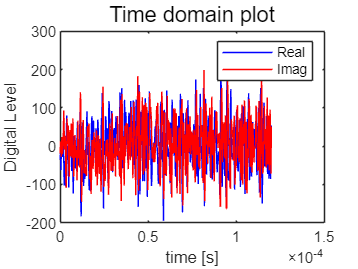

% show raw data (mixing -> ADC, complex)
% only Chirp #1, Rx1, Frame #1
figure(1), clf; hold on;
t=linspace(0,T_ramp,ADC_Samples);
plot(t,real(raw(:,1,1,1)),'b-');
plot(t,imag(raw(:,1,1,1)),'r-');box on; xlabel('time [s]'), ylabel('Digital Level'), title('Time domain plot','fontsize',13)
legend('Real','Imag'); 

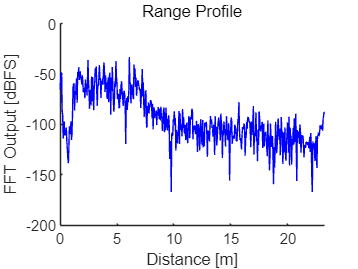


if win
    % Hanning Window
    w = hann(ADC_Samples, 'periodic');
    raw = raw .* w;
end

% % Hamming Window
% w = hamming(ADC_Samples, 'periodic');
% raw = raw .* w;

rangeFFT = fft(raw, [], 1); % [ADC_Samples, No_Chirp, numRX, frameID] -> % [distance, No_Chirp, numRX, frameID]

yy = (0:N_r-1) * dy; %[m] range
% chirp1, Rx1, Frame1
raw1=raw(:,1,1,1);
raw1FFT=fft(raw1);
figure; %clf, plot(yy,20*log(abs(raw1FFT)/2^16),'r-')
hold on; plot(yy,20*log(abs(rangeFFT(:,1,1)/2^16)),'b-') %P_dBFS=20log(sqrt(P)/Full_Scale), 16bits: Full_Scale=2^16
xlabel('Distance [m]'), ylabel('FFT Output [dBFS]'), title('Range Profile'); ylim([-200 0])
hold off

## Range-Doppler

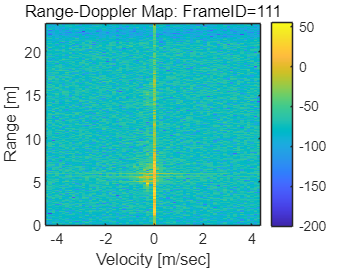


% Complex2X ADC Mode인 경우
if is2X == true
    dopplerFFT = fftshift(fft(rangeFFT, [], 2)); % [distance, No_Chirp, numRX, frameID] -> % [distance, doppler, numRX, frameID]

    % extract only positive distance, 음의 주파수로 인해 발생하는 마이너스 거리를 제거
    dopplerFFT = dopplerFFT(ADC_Samples/2+1:ADC_Samples,:,:,:);
    figure;
    for frameID=1:10:No_Frame
        rangeDopplerMag=squeeze(abs(dopplerFFT(:,:,1,frameID)));
        yy = (-N_r/2:N_r/2-1) * dy;
        vv = (-N_c/2:N_c/2-1) * dv;
        imagesc(vv,yy, 20*log(rangeDopplerMag/2^16)); ylabel('Range [m]'); xlabel('Velocity [m/sec]'); colorbar
        title(['Valid Range-Doppler Map: FrameID=' num2str(frameID)]); axis xy
        pause(0.1)
    end
else % Complex1X ADC Mode
    
    if win
        % Hanning Window
        w = hann(No_Chirp, 'periodic');
        w = reshape(w, [1, No_Chirp]);
        rangeFFT = rangeFFT .* w;
    end

    % % Hamming Window
    % w = hamming(No_Chirp, 'periodic');
    % w = reshape(w, [1, No_Chirp]);
    % rangeFFT = rangeFFT .* w;

    dopplerFFT = fftshift(fft(rangeFFT, [], 2), 2); % [distance, No_Chirp, numRX, frameID] -> % [distance, doppler, numRX, frameID]
    figure;
    for frameID=1:10:No_Frame
        rangeDopplerMag=squeeze(abs(dopplerFFT(:,:,1,frameID)));
        yy = (0:N_r) * dy;
        vv = (-N_c/2:N_c/2-1) * dv;
        imagesc(vv,yy, 20*log(rangeDopplerMag/2^16), [-200 55]); ylabel('Range [m]'); xlabel('Velocity [m/sec]'); colorbar
        title(['Range-Doppler Map: FrameID=' num2str(frameID)]); axis xy
        pause(0.1)
    end
end

## CFAR Detection

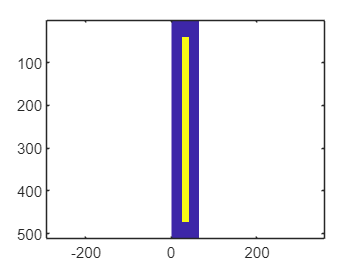

% Parameters
guardCells = [8 8];        % [GuardCells in Range, GuardCells in Doppler]
trainingCells = [32 16];    % [TrainingCells in Range, TrainingCells in Doppler]
falseAlarmRate = 1e-16;     % false alarm rate

% 2D CFAR
cfar2D = phased.CFARDetector2D('GuardBandSize',guardCells,...
    'TrainingBandSize',trainingCells,...
    'ProbabilityFalseAlarm',falseAlarmRate,...
    'ThresholdOutputPort',true);

% CFAR이 탐지할 영역(cutidx) 선언
N_r = size(dopplerFFT, 1);
N_c = size(dopplerFFT, 2);
Ngc = cfar2D.GuardBandSize(2);
Ngr = cfar2D.GuardBandSize(1);
Ntc = cfar2D.TrainingBandSize(2);
Ntr = cfar2D.TrainingBandSize(1);

N = (Ntr * 2 + Ngr * 2 + 1) * (Ntc * 2 + Ngc * 2 + 1) - (Ngr * 2 + 1) * (Ngc * 2 + 1);

cutidx = [];
colstart = Ntc + Ngc + 1;
colend = N_c - ( Ntc + Ngc);
rowstart = Ntr + Ngr + 1;
rowend = N_r - ( Ntr + Ngr);

for m = colstart:colend
    for n = rowstart:rowend
        cutidx = [cutidx,[n;m]];
    end
end
ncutcells = size(cutidx,2);

% cutidx를 이미지로 시각화
cutimage = zeros(N_r,N_c);
for k = 1:ncutcells
    cutimage(cutidx(1,k),cutidx(2,k)) = 1;
end
imagesc(cutimage)
axis equal

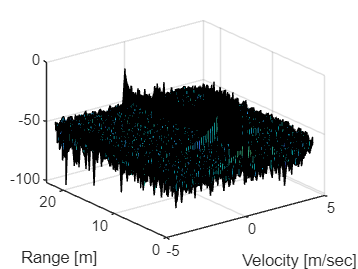


yy = (0:N_r-1) * dy;
vv = (-N_c/2:N_c/2-1) * dv;

[X, Y] = meshgrid(vv,yy);
mag_dopplerFFT = abs(dopplerFFT(:,:,1,1)/2^16);
mag_dopplerFFT = mag_dopplerFFT - min(mag_dopplerFFT(:));
mag_dopplerFFT = mag_dopplerFFT / max(mag_dopplerFFT(:));
figure; surf(X,Y, 20*log10(mag_dopplerFFT)); ylabel('Range [m]'); xlabel('Velocity [m/sec]')

## Result

figure(10);
for i=1:1:No_Frame
    % dets : 탐지 point 표시, th : threshold value(뒤에서 사용되지는 않음)
    magnitude=abs(dopplerFFT);
    [dets,th] = cfar2D(magnitude(:,:,:,i),cutidx);
    
    % RCS 최대값 index
    m = magnitude(:,:,1,i);
    m = m(:);
    [max_range_idx, max_doppler_idx] = find(magnitude(:,:,1,i) == max(m));
    
    % CFAR 결과를 기반으로 타겟 포인트 탐지
    detimg = zeros(N_r, N_c);
    for k = 1:ncutcells
        detimg(cutidx(1, k), cutidx(2, k)) = dets(k);
    end
    % figure; imagesc(vv,yy, magnitude(:,:,1,1)); ylabel('Range [m]'); xlabel('Velocity [m/sec]'); colorbar; axis xy
    % figure; imagesc(vv,yy, detimg);  ylabel('Range [m]'); xlabel('Velocity [m/sec]'); axis xy
    
    % CFAR 결과에서 유효한 탐지 포인트의 인덱스 추출
    [range_idx, doppler_idx] = find(detimg > 0);
    
    % Angle FFT 적용 (각도 추정)
    % RX1과 RX2는 세로로 배열, RX2, RX3, RX4는 가로로 배열됨을 고려
    Num_AngleBins = 32;  % Angle FFT를 위한 bin 개수 (각도 분해능으로 -90도~90도를 몇개로 분할할 것인지 정함)
    angleFFT_Horizontal = zeros(length(range_idx), Num_AngleBins);
    angleFFT_Vertical = zeros(length(range_idx), Num_AngleBins);
    
    for idx = 1:length(range_idx)
        % Horizontal 방향: RX2, RX3, RX4
        RX_data_horizontal = dopplerFFT(range_idx(idx), doppler_idx(idx), 2:4, 1);
        angleFFT_Horizontal(idx, :) = fftshift(fft(RX_data_horizontal, Num_AngleBins));
        
        % Vertical 방향: RX1, RX2
        RX_data_vertical = dopplerFFT(range_idx(idx), doppler_idx(idx), [1, 2], 1);
        angleFFT_Vertical(idx, :) = fftshift(fft(RX_data_vertical, Num_AngleBins));
    end
    
    max_RX_data_horizontal = dopplerFFT(max_range_idx, max_doppler_idx, 2:4, 1);
    max_angleFFT_Horizontal = fftshift(fft(max_RX_data_horizontal, Num_AngleBins));
    max_angleFFT_Horizontal = reshape(max_angleFFT_Horizontal, [1, Num_AngleBins]);
    
    max_RX_data_vertical = dopplerFFT(max_range_idx, max_doppler_idx, [1, 2], 1);
    max_angleFFT_Vertical = fftshift(fft(max_RX_data_vertical, Num_AngleBins));
    max_angleFFT_Vertical = reshape(max_angleFFT_Vertical, [1, Num_AngleBins]);
    
    % Magnitude 계산 (Angle FFT 결과의 절댓값)
    angleMagnitudes_Horizontal = abs(angleFFT_Horizontal);
    angleMagnitudes_Vertical = abs(angleFFT_Vertical);
    max_angleMagnitudes_Horizontal = abs(max_angleFFT_Horizontal);
    max_angleMagnitudes_Vertical = abs(max_angleFFT_Vertical);
    
    % Horizontal 및 Vertical에서 가장 큰 값을 가지는 각도 추정
    % 1 ~ Num_AngleBins 사이로 주파수가 표현
    [~, angle_idx_horizontal] = max(angleMagnitudes_Horizontal, [], 2);
    [~, angle_idx_vertical] = max(angleMagnitudes_Vertical, [], 2);
    [~, max_angle_idx_horizontal] = max(max_angleMagnitudes_Horizontal, [], 2);
    [~, max_angle_idx_vertical] = max(max_angleMagnitudes_Vertical, [], 2);
    
    % 각도 계산 (Index를 실제 각도로 변환)
    % Normalized Frequency로 -0.5 ~ 0.5 사이로 표현이 되고, 이를 각도로 변환
    angles_horizontal = asin(((angle_idx_horizontal - Num_AngleBins / 2) / Num_AngleBins)*2);
    angles_vertical = asin(((angle_idx_vertical - Num_AngleBins / 2) / Num_AngleBins)*2);
    max_angles_horizontal = asin(((max_angle_idx_horizontal - Num_AngleBins / 2) / Num_AngleBins)*2);
    max_angles_vertical = asin(((max_angle_idx_vertical - Num_AngleBins / 2) / Num_AngleBins)*2);
    
    % Range 계산
    % dy : Range Resolution
    ranges = range_idx * dy;
    
    % 3D 포인트 클라우드 생성
    x = ranges .* cos(angles_horizontal);  % X 좌표 (수평 각도) % 바라보는 방향 거리
    y = -1 * ranges .* sin(angles_horizontal);  % Y 좌표 (수평 각도) % 좌우 거리
    z = ranges .* sin(angles_vertical);    % Z 좌표 (수직 각도) % 높이
    
    % RCS 최대값 point 위치 생성
    max_ranges = max_range_idx * dy;
    max_x = max_ranges .* cos(max_angles_horizontal);  % X 좌표 (수평 각도) % 바라보는 방향 거리
    max_y = max_ranges .* sin(max_angles_horizontal);  % Y 좌표 (수평 각도) % 좌우 거리
    max_z = max_ranges .* sin(max_angles_vertical);    % Z 좌표 (수직 각도) % 높이
    
    % Point Cloud 생성 (X, Y, Z 좌표로 변환된 3D 포인트)
    pointCloud = [x(:), y(:), z(:)];
    
    % 포인트 클라우드 시각화
    drawnow
    % scatter3(pointCloud(:, 1), pointCloud(:, 2), pointCloud(:, 3), 'filled', 'MarkerFaceColor',[0 0 1]);
    scatter(pointCloud(:, 1), pointCloud(:, 2), 72, 'filled', 'MarkerFaceColor',[0 0 1]);
    hold on;
    scatter(0, 0, 144,'<', 'filled', 'MarkerEdgeColor', [1 0 0], 'MarkerFaceColor', [1 1 1])
    % scatter3(max_x, max_y, max_z, 36, 'MarkerFaceColor',[1 0 0]);
    xlabel('X (Range*cos(Horizontal Angle))');
    ylabel('Y (Range*sin(Horizontal Angle))');
    zlabel('Z (Range*sin(Vertical Angle))');
    title('2D Point Cloud');
    xlim([-0.1, 6]); ylim([-2 2]); %zlim([-1 1]);
    grid on;
    if mod(i, 10) == 0
        disp('reset')
        hold off
        figure(10);
    end
    pause(0.01)
end

reset
reset
reset
reset
reset
reset
reset
reset
reset
reset
reset
reset


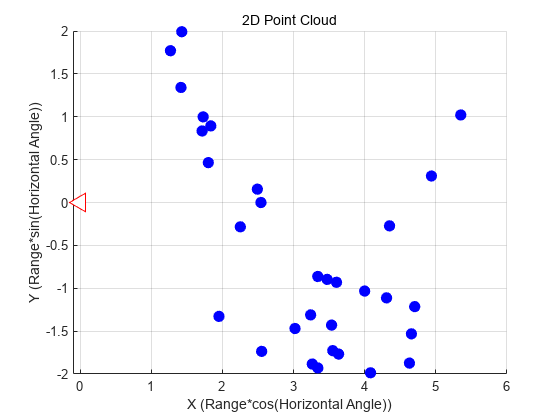

hold off

Window func.

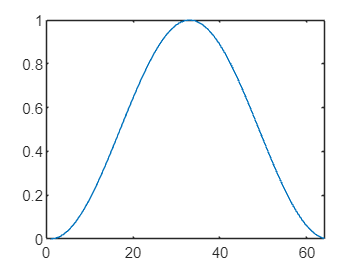

w_size = 64;

w = hann(w_size, 'periodic');
figure; plot(w)

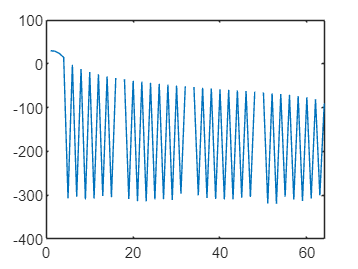

w_freq = db(abs(fft(w, w_size * 2)));
w_freq = w_freq(1:w_size);
figure; plot(w_freq)

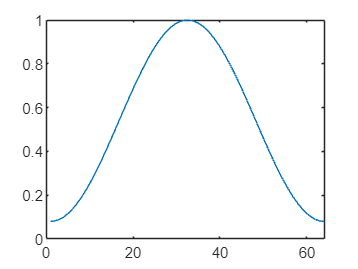


% wvtool(w)

w = hamming(w_size);
figure; plot(w)

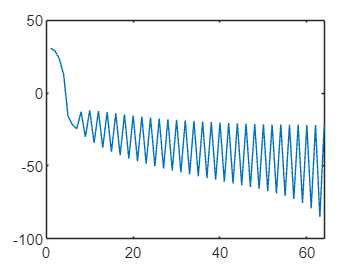

w_freq = db(abs(fft(w, w_size * 2)));
w_freq = w_freq(1:w_size);
figure; plot(w_freq)


% wvtool(w)

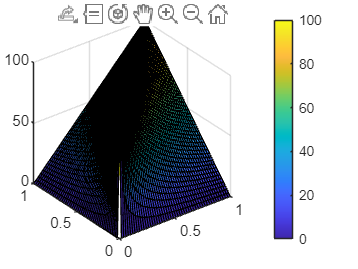

clear; clc

x = linspace(0, 1, 50);
x1 = repmat(x, 50, 1);
x2 = x1';
X = 1 ./ (exp(abs(log(x1) - log(x2)))) * 100;

figure; surf(x, x, X); colorbar